% script for analyzing twin-grain boundary intersection
%
% chenzhe, 2019-06-24 note
% use stepwiselm() to fit linear model and select the most relavant
% variable for twin growth rate.


clear;
addChenFunction;

added Chen Functions



% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\20190222_1246_twin_at_boundary_result.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

## [data] strain data. Convert into v7.3 for partial loading

clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1_insitu_compression\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_5


v7.3 file already exist


## (0) load data, using SF threshold values to assign active twin system, and make maps

Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));


## (7) Summarize, does twin growth rate depend on something: model rate as function of something...

close all;
um_per_dp = 360/4096*5;

% if have rate, it means it already activated in previous strain level.  Otherwise, rate = NaN.  
variableNames = {'iE','ID','ts','variant','SF','SF_normalized','SF_int','gVol', 'gDia_um', 'eG','vols','vol','rates','rate'}; 
T = cell2table(cell(0,length(variableNames)));
T.Properties.VariableNames = variableNames;

eGs = -strainPauses(1:iE_stop); % make it positive value, compressive strain
for iS = 1:length(struCell{iE_start})
    tvol_allT_allE = zeros(6,iE_stop);
    for iE = iE_start:iE_stop
        tvol_allT_iE = struCell{iE}(iS).tVol(:);
        % if detect vol decrease to 0, just make it the same as the previous iE 
        if iE>iE_start  
            ind = (tvol_allT_iE==0)&(tvol_allT_iE<tvol_allT_allE(:,iE-1));
            tvol_allT_iE(ind) = tvol_allT_allE(ind,iE-1);
        end
        tvol_allT_allE(:,iE) = tvol_allT_iE;
    end
    tvol_allT_allE(tvol_allT_allE==0) = nan;
    
    % when comparing twin vol, it's not proper to compare absolute size, because grain size is different  
    % but when comparing twin growth speed, it's better to compare advancing rate in um/pixels (currently I don't have this ability to count individual twins, number of twin fragments, etc)   
    for it = 1:6
        iEs = find(tvol_allT_allE(it,:)>0); % find all iEs with
        for ii = 1:length(iEs)
            iE = iEs(ii);
            ts = struCell{iE}(iS).tLabel(it);
            SF = struCell{iE}(iS).tSF(it);
            SF_normalized = SF/max(struCell{iE}(iS).tSF);
            SF_int = floor(SF/0.1);
            [~,variant]=ismember(SF,sort(struCell{iE}(iS).tSF,'descend'));
            gVol = struCell{iE}(iS).gVol;   
            gDia_um = sqrt(gVol*4/pi)*um_per_dp;
            eG = eGs(iE);
            vols = tvol_allT_allE(it,:)/gVol;    % as pct of grain size  
            vol = vols(iE);
            rates = (vols(2:end) - vols(1:end-1))./(eGs(iE_start:iE_stop)-eGs(iE_start-1:iE_stop-1));
            rate = rates(iE-1);
            T = [T; {iE, struCell{iE}(iS).gID, ts, variant, SF, SF_normalized, SF_int, gVol, gDia_um, eG, vols, vol, rates, rate}];
        end
    end
end
display(T);

T = 1548×14 table
    iE    ID    ts    variant      SF       SF_normalized    SF_int       gVol       gDia_um     eG                             vols                              vol                     rates                   rate 
    __    __    __    _______    _______    _____________    ______    __________    _______    _____    ___________________________________________________    ________    _________________________________    ______
    3     28    22       2       0.40223       0.93692         4       1.4

summary(T);

Variables:
    iE: 1548×1 double
        Values:
            Min        2  
            Median     4  
            Max        5  
    ID: 1548×1 double
        Values:
            Min         28
            Median     834
            Max       1622
    ts: 1548×1 double
        Values:
            Min        19 
            Median     21 
            Max        24 
    variant: 1548×1 double
        Values:
            Min           1    
            Median        1    
            Max           4    
    SF: 1548×1 double
        Values:
            Min       0.16534
            Median    0.45795
            Max       0.49948
    SF_normalized: 1548×1 double
        Values:
            Min           0.45389    
            Median              1    
            Max                 1    
    SF_int: 1548×1 double
        Values:
            Min          1    
          

## Model by stepwiselm()

iE = 5;
t = T(T.iE==iE,:);
summary(t);

Variables:
    iE: 564×1 double
        Values:
            Min        5  
            Median     5  
            Max        5  
    ID: 564×1 double
        Values:
            Min         28
            Median     851
            Max       1622
    ts: 564×1 double
        Values:
            Min        19 
            Median     21 
            Max        24 
    variant: 564×1 double
        Values:
            Min           1    
            Median        1    
            Max           4    
    SF: 564×1 double
        Values:
            Min       0.16534
            Median    0.45656
            Max       0.49948
    SF_normalized: 564×1 double
        Values:
            Min           0.45389    
            Median              1    
            Max                 1    
    SF_int: 564×1 double
        Values:
            Min          1    
            Media

mdl = stepwiselm(t,'interactions','ResponseVar','rate','PredictorVars',{'gDia_um','SF','gVol','eG'})

1. Removing SF:eG, FStat = NaN, pValue = NaN
2. Removing gVol:eG, FStat = NaN, pValue = NaN
3. Removing gDia_um:eG, FStat = NaN, pValue = NaN
4. Removing eG, FStat = NaN, pValue = NaN
5. Removing SF:gVol, FStat = 5.4806e-06, pValue = 0.99813
6. Removing gVol:gDia_um, FStat = 0.43456, pValue = 0.51005
7. Removing gVol, FStat = 0.0042993, pValue = 0.94775
8. Removing SF:gDia_um, FStat = 0.6379, pValue = 0.42484


mdl = Linear regression model:
    rate ~ 1 + SF + gDia_um

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________
    (Intercept)      -0.41609       1.7461    -0.23829       0.81175
    SF                 15.536        3.711      4.1866    3.3258e-05
    gDia_um        -0.0084748    0.0038041     -2.2278      0.026321

Number of observations: 523, Error degrees of freedom: 520
Root Mean Squared Error: 4.62
R-squared: 0.0427,  Adjusted R-Squared 0.039
F-statistic vs. constant model: 11.6, p-value = 1.18e-05

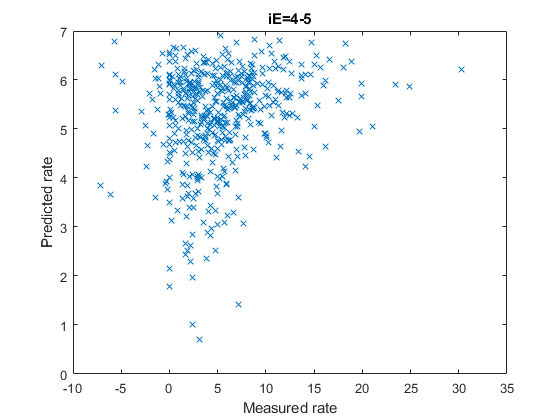

figure;
plot(t.rate, mdl.predict(t),'x');
xlabel('Measured rate');
ylabel('Predicted rate');
title(['iE=',num2str(iE-1),'-',num2str(iE)]);